# TDD Reciprocity-Based PDSCH MU-MIMO Using SRS

This example implements downlink multiuser multiple-input multiple-output (MU-MIMO) by exploiting channel reciprocity in a time division duplex (TDD) scenario. The example shows how to determine beamforming weights for physical downlink shared channel (PDSCH) transmission by using channel estimates based on uplink sounding reference signals (SRS) transmitted for each user, and how to schedule PDSCHs for multiple users in the same time and frequency resources.

## Introduction

TDD systems use the same frequency band for uplink (UL) and downlink (DL) transmissions. The radio channel is reciprocal because it has the same characteristics in both UL and DL directions. Exploiting this reciprocity, you can use a UL transmission to obtain a channel estimate and then use this channel estimate to calculate parameters, including beamforming, for a DL transmission. This method is known as reciprocity-based beamforming.

This example implements downlink MU-MIMO by calculating a channel estimate for multiple users based on their SRS transmissions. Assuming reciprocity, the example then uses these channel estimates to select a set of users to be scheduled for PDSCH transmission and calculates DL beamforming weights for PDSCH transmissions to those users. When the base station has a sufficient number of antennas, it is possible to beamform PDSCH transmissions for a set of users in the same time and frequency resources such that the users suffer little interference from each other.

This example schedules SRS transmissions for all UEs in the UL part of the special slot, and schedules PDSCH transmissions for UEs chosen by the user selection algorithm in DL slots and the DL part of special slots.

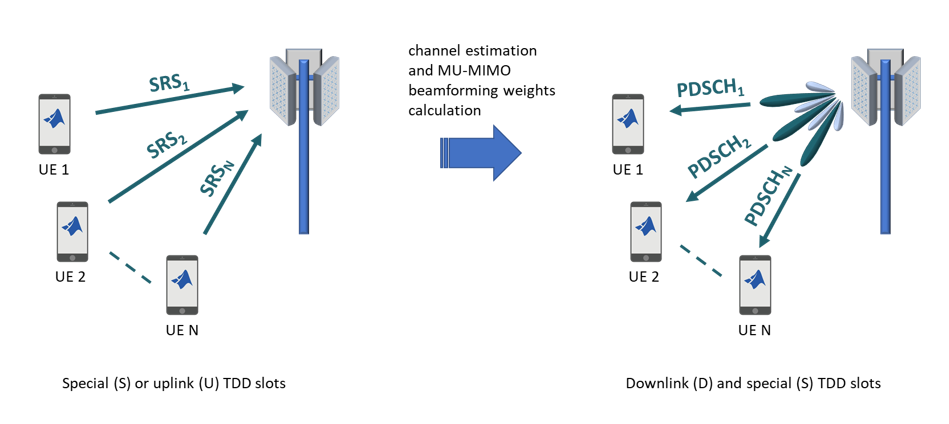

The example offers a choice of MU-MIMO precoding algorithms and allows the number of layers scheduled in the same time and frequency resources to be configured. Finally, the example measures the capacity of the overall cell relative to a single-layer user, showing that the capacity is higher than could be achieved by scheduling a single user.

### Simulation Assumptions

The example uses these assumptions.

- The SRS configuration allows for up to 16 UEs to be scheduled.

- The number of layers assigned to a given UE is random (either 1, 2, or 4) and is fixed for the duration of the simulation.

- The number of SRS antenna ports is equal to the number of layers assigned.

- For the zero forcing, regularized zero forcing, and block diagonalization precoding methods, the number of SRS antenna ports is equal to the number of physical antennas, that is, no spatial filtering of SRS ports onto a larger set of physical antennas. For joint spatial division multiplexing precoding, hybrid precoding is used so the number of SRS antenna ports is equal to the number of RF chains, which is less than the number of physical antennas.

- The number of UE transmit antennas is equal to the number of SRS antenna ports, that is, full channel sounding is used.

- The precoding resource block group (PRG) bundle size is the same for all UEs.

- PDSCH is not scheduled in the downlink slots of the first frame occurring prior to the first special slot, because no channel estimate is yet available.

- Demodulaton reference signal (DM-RS) configuration type is type 1 and DM-RS length is 2, that is, 8 orthogonal DM-RS ports can be scheduled. For scheduling more users, the example employs nonorthogonal DM-RSs by changing the scrambling identity. 

- HARQ is not supported.

- All UEs are synchronized to within the cyclic prefix length based on the initial acquisiton and transmission timing adjustment procedures, as described in TS 38.213 Sections 8 and 4.2 [1]. A timing offset within the cyclic prefix length manifests as a phase shift in the frequency domain and is compensated by the channel estimation and equalization. 

- All UEs are received with equal power after averaging across channel variations due to fading. 

## Simulation Parameters

Specify the number of UEs, the number of frames to simulate, and the SNR for the downlink and the uplink, assuming that the SNR is the same for all users. For an explanation of the SNR definition that this example uses, see [SNR Definition used in Link Simulations](docid:5g_ug#mw_37cef3ca-2f4b-433d-8d68-117a881ca5fd).

clear;
%可调参数：
% txpower 所有天线上的总发射功率（dbm）
% bandwidth 带宽（可选5 10 15 20 25 30 35 40 45 50 60 70 80 90 100 MHz）
% SCS 子载波间隔（FR1时可选 15 30 60 KHz）
% NRB 由bandwidth-SCS映射表给出
% DAC_resolution 量化精度
% numUEs 用户数
% numRFs 射频链路数
% numAntennas 天线数 [AntRow 8 2] AntRow取值1 2 3 4分别对应16，32，48，64天线
% numStream 数据流数 

txpower = 43;
numAntennas_element = 192; %16 32 48 64
antenna_gain = 10*log10(numAntennas_element); 


bandwidth = 100;
SCS = 30;
%带宽 SCS映射表
BandwidthRange = [5, 10, 15, 20, 25, 30, 35, 40, 45, 50, 60, 70, 80, 90, 100];
SCSRange = [15 30 60];
A = [25,  52,  79,  106, 133, 160, 188, 216, 242, 270, NaN, NaN, NaN, NaN, NaN;
     11,  24,  38,  51,  65,  78,  92,  106, 119, 133, 162, 189, 217, 245, 273;
     NaN, 11,  18,  24,  31,  38,  44,  51,  58,  65,  79,  93,  107, 121, 135;];
NRB = A(find(SCSRange == SCS),find(BandwidthRange == bandwidth));
numUEs = 12;        % Total number of UEs served by the base station
radius_BS = 700;    % 3.5 UMa 覆盖范围250米
numFrames = 1;      % Total number of frames to simulate
SNRdBDL = cal_SNR(numUEs, radius_BS,NRB, SCS, txpower+antenna_gain);       % Downlink SNR in dB
SNRdBUL = 20;       % Uplink SNR in dB
DAC_resolution = 12;
numAntennas = 32; %16 32 48 64
numStream = 16;



## Base Station Configuration

### Carrier Configuration

Set the carrier parameters, specifying 51 resource blocks at 30 kHz subcarrier spacing, which corresponds to a channel bandwidth of 20 MHz.

carrier = nrCarrierConfig;

carrier.SubcarrierSpacing = SCS;
carrier.NSizeGrid = NRB;
BW = bandwidth*1e6;
% DAC_bits = DAC_resolution;
DAC_bits = 14;
OSR = 6;
transmiter_power = txpower;
NRF_chain = numAntennas;
NRB = NRB;
U = numStream;
M = numAntennas;

total_power=calculate_power(1e9,BW,DAC_bits,OSR,transmiter_power,NRF_chain,NRB,U,M,carrier);

### TDD Configuration

The example considers a TDD configuration consisting of a number of downlink slots (D), followed by a special slot (S), followed by a number of uplink slots (U). The special slot represents a switchpoint from downlink to uplink transmission and therefore contains downlink symbols, followed by empty guard symbols, followed by uplink symbols. The number of dowlink or uplink symbols in the special slot can be zero. This example schedules SRS transmissions in the uplink part of the special slot, and schedules PDSCH transmissions in downlink slots and in the downlink part of special slots.

Represent the TDD slot pattern by an array of strings specifying the slot type. 

tddPattern = ["S" "U" "U" "D" "D" "D" "D" "D" "D" "D"];

disp("Cyclic slot pattern:")
disp("Slot " + string((0:length(tddPattern)-1)') + ": " + tddPattern(:))

Represent the special slot configuration by a three-element vector specifying the number of downlink symbols, guard symbols, and uplink symbols in the special slot.

specialSlot = [6 4 4];

The total number of symbols in the special slot configuration must match the number of symbols in a slot given by `carrier.SymbolsPerSlot`.

if(sum(specialSlot)~=carrier.SymbolsPerSlot)
    error(['specialSlot must contain ' num2str(carrier.SymbolsPerSlot) ' symbols.']);
end


### Antenna Array Size

Specify the antenna array size for the base station (BS). Assume a rectangular array. The antenna array size is a vector `[M N P]`, where `M` is the number of rows, `N` is the number of columns and `P` is the number of polarizations in the antenna array.

AntRow = numAntennas/16;
bsAntSize = [AntRow 8 2];

## UE Configuration

### Spatial Configuration

Specify if UE locations are randomly scattered throughout the cell sector or clustered into groups. To scatter randomly, set `numGroups` to 1. If clustering into groups, the number of UEs will be evenly split as much as possible amongst the groups. The number of groups must not exceed the number of UEs.

numGroups = 1;

% Assign each UE a spatial group
g = (1:numGroups).*ones(ceil(numUEs/numGroups),1);
groups = g(1:numUEs);

### Number of Layers and Antenna Array Sizes

Randomly select the number of layers per UE (1, 2, or 4).

% Reset random generator for reproducibility
rng('default');

% Number of layers for each UE
numLayers = pow2(randi([0 2],[1 numUEs]))

The number of layers determines the antenna array size for each UE according to this table.


$$\begin{array}{c|c}
\text{Number of Layers} & \text{UE Antenna Array Size} \\
\hline\\
1 & [1 \ 1 \ 1] \\
2 & [1 \ 1 \ 2] \\
4 & [1 \ 2 \ 2]
\end{array}$$


% Number of rows, columns and polarizations in rectangular array for each UE
ueAntSizes = 1 + (numLayers.' > [4 2 1])

### SRS Configuration

Configure the SRS parameters for each UE. The SRSs for all UEs are configured to be transmitted in a special slot, or in an uplink slot if there is no special slot (or if it contains no uplink symbols). The example performs time-division multiplexing (TDM) of SRSs by using different OFDM symbol numbers and frequency-division multiplexing (FDM) by using different comb offsets. For each UE, the number of SRS ports is configured to be equal to the number of layers for that UE. 

SRSs = hMultiUserSRS(tddPattern,specialSlot,carrier,numLayers);

For more information on SRS parameterization, see the [NR SRS Configuration](docid:5g_ug#mw_8bf32f56-e02c-4fd4-9ad6-863f1a40e45e) example.

### PDSCH and DL-SCH Configuration

Configure the PDSCH and DL-SCH parameters for each UE with these parameters.

- Rate 3/4 coding and 64-point quadrature amplitude modulation (64-QAM)

- DM-RS configuration type 1 and DM-RS length 2, which provides 8 orthogonal DM-RS ports, see TS 38.211 Table 7.4.1.1.2-1 [5]

- PRG bundle size of 2, see TS 38.214 Section 5.1.2.3 [6]

Configure the appropriate number of layers for each UE and set the RNTI equal to the UE number (`1...numUEs`).

PDSCHs = hMultiUserPDSCH(numLayers);
for ue = 1: numUEs
% 基于SNR调整调制方案
if SNRdBDL(ue) < 10
PDSCHs(ue).Config.Modulation = 'QPSK';
elseif SNRdBDL(ue) < 20
PDSCHs(ue).Config.Modulation = '16QAM';
else
PDSCHs(ue).Config.Modulation = '64QAM';
end
end

You can configure further PDSCH parameters for each transmission during the user selection process by using the `hMultiUserSelection` function.

For more information on PDSCH parameterization, see the [NR PDSCH Resource Allocation and DM-RS and PT-RS Reference Signals](docid:5g_ug#mw_5e942615-6195-432a-a498-99d59e558290) example.

## Algorithmic Parameters

### MU-MIMO Precoding Method

The example supports these precoding methods.

- `     'BD'`: Block diagonalization, as described by Spencer, Q.H., et al. in [2]. Note that the implementation uses the [blkdiagbfweights](docid:comm_ref#mw_976dda49-7ac8-40ae-b03b-a8c31bdd1052) function.

- `     'ZF'`: Zero forcing, as described by Peel, C.B., et al. in [3].

- `    'RZF'`: Regularized zero forcing, as described by Peel, C.B., et al. in [3].

- '`JSDM-JGP`': Joint spatial division multiplexing with joint group processing (JGP), as described by Adhikary, A., et al. in [7].

- '`JSDM-PGP`': Joint spatial division multiplexing with per-group processing (PGP), as described by Adhikary, A., et al. in [7].

Configure the precoding method that is used to determine the beamforming weights for each PDSCH during user selection. 

algParameters = struct;
algParameters.PrecodingMethod = 'RZF'; %RZF, JSDM-JGP, JSDM-PGP

Configure the number of layers that the user selection algorithm schedules in each PRG in each slot. This value is the total number of layers scheduled across all users in any given PRG in this slot. The user selection algorithm is based on proportional fair (PF) scheduling considering each PRG separately. 

algParameters.ScheduledLayers = numStream;

### **Hybrid Precoding using Joint Spatial Division Multiplexing (JSDM)**

This example provides an option to use JSDM for the MU-MIMO precoding method.  JSDM enables massive MIMO by using a hybrid precoding architecture where the number of RF chains is much less than the number of physical antennas.  In this example, the number of RF chains equals the number of scheduled layers when JSDM is selected. For more information on JSDM, see the [Massive MIMO Hybrid Beamforming](docid:comm_ug#example-MassiveMIMOHybridBeamformingExample) example. Note that the implementation uses the [jsdmrfweights](docid:phased_ref#mw_6e1c029f-0d5a-40ab-968e-aa762dd27113) and [jsdmbbweights](docid:phased_ref#mw_0b4aefff-5376-4882-80e2-0af4f9480dc4) functions which require the Phased Array System Toolbox.

To accommodate the needs of JSDM, the following parameters changes are recommended:

- Increase the number of antennas. Massive MIMO generally implies antenna arrays larger than 64 elements.

- Limit the number of groups to 2-4 (at least two groups are required). JSDM allocates a fixed number of layers to each group, which may affect PDSCH scheduling and cause some UEs to not receive data due to the PF scheduling if there aren't enough layers in the group. In this example, the number of layers assigned to each group is split evenly from the number of scheduled layers (the last group will receive the leftover layers if the layers cannot be split evenly).

- JGP has better performance than PGP, because the PGP precoding matrix is truncated to reflect less CSI. 

- Limit the number of scheduled layers to be less than the total number of UEs (for PGP) or less than the total number of UE layers (for JGP). JSDM RF beamforming is sensitive to the rank measurements of the group spatial covariances. In this example, the measured rank of each group is limited to the number of users.

- Adjusting the modulation order can lower the bit error rate in exchange for lower throughput. The default is set to 64-QAM.

Upon selection of JSDM, the example will enable channel filtering and disable perfect channel estimation.

### **Channel Estimator Configuration**

The logical variable `PerfectChannelEstimator` controls channel estimation behavior. When you set this variable to `true`, the example uses perfect channel estimation for SRS and PDSCH reception. Otherwise, the example uses practical channel estimation based on the values of the received SRS and PDSCH DM-RS.

algParameters.PerfectChannelEstimator = false;

## CDL Channel Models

Configure a propagation channel model for each UE. The `hMultiUserChannels` function uses the [nrCDLChannel](docid:5g_ref#mw_sysobj_nrCDLChannel) object to configure clustered delay line (CDL) channels. Use this function to create an initial channel object with CDL-A delay profile, 100 ns delay spread, and 5 Hz Doppler shift. The function then configures different channels for each UE by modifying the initial object to:

- Simulate the effect of different UEs in different locations in the environment around the base station. Each UE has an azimuth and zenith angle relative to the base station; the angles of departure for each cluster are offset by these angles. When `numGroups`=1, the UEs are configured to have randomly selected azimuth and zenith angles; otherwise, the UEs are configured to be clustered in spatial groups such that the azimuth and zenith angles for the grouped UEs are similar.

- Configure the UE antenna array according to the antenna array size chosen in Number of Layers and Antenna Array Sizes.

- Set a different value of the `Seed` property. This ensures that the channel for each UE has independent fast fading.

delayProfile = 'CDL-A';
delaySpread = 100e-9;
maximumDopplerShift = 5;
channels = hMultiUserChannels(delayProfile,delaySpread,maximumDopplerShift,bsAntSize,ueAntSizes,groups);

To visualize the configuration of a CDL channel, see the [Visualize CDL Channel Model Characteristics](docid:5g_ug#mw_18932125-0e92-4208-8530-2df349bb2d0c) example. To create CDL channel model parameters by using the output of a ray tracing analysis, see the [CDL Channel Model Customization with Ray Tracing](docid:5g_ug#mw_788a51e3-b40f-402d-ace3-d4e701ea8781) example.

## MU-MIMO Throughput Simulation Using Reciprocity-Based Beamforming

This diagram shows the structure of the throughput simulation.

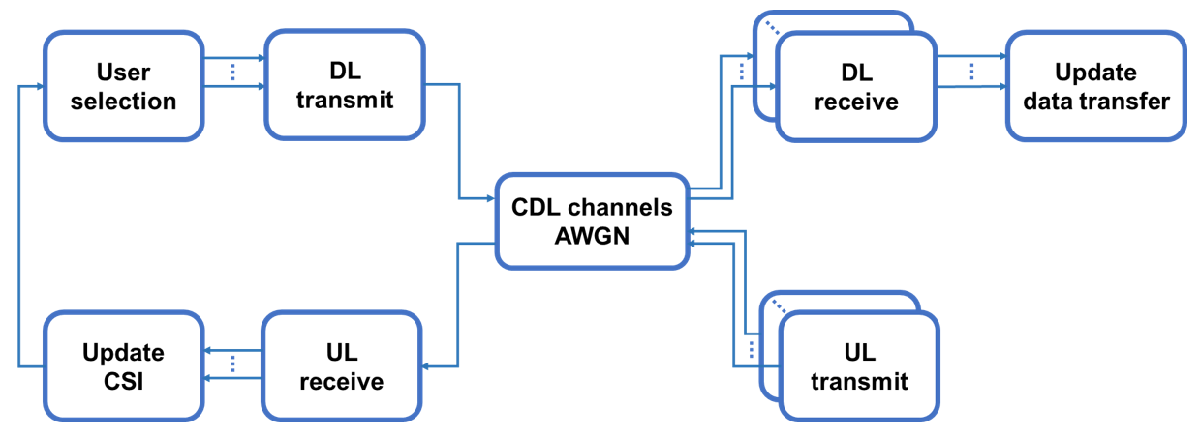

For slots scheduled for SRS:

- **UL transmit:** Generate the SRS waveform for each UE.

- **CDL channels, AWGN:** For each UE, send the waveform through the channel, combine the channel outputs at the base station, and add noise.

- **UL receive: **For each UE, perform SRS-based channel and noise estimation. For more information, see the [NR Uplink Channel State Information Estimation Using SRS](docid:5g_ug#mw_8e8a81bb-0612-4847-89a3-43ddc89349f8) example.

- **Update CSI:** Record the channel and noise estimates for use in subsequent slots.

For slots scheduled for PDSCH:

- **User selection:** Considering the most recent CSI for all UEs, determine which UEs to schedule for PDSCH and configure PDSCH parameters (allocated RBs, beamforming, DM-RS ports, scrambling identity).

- **DL transmit:** For each UE, perform DL-SCH encoding of data and generate and beamform the PDSCH. Sum the beamformed PDSCHs to form the transmitted signal.

- **CDL channels, AWGN:** Send the transmitted signal through the channel for each UE and add noise to create the received waveform for each UE.

- **DL receive:** For each UE, demodulate the received waveform, demodulate the PDSCH and decode the DL-SCH.

- **Update data transfer:** Record the transport block size (TBS) and cyclic redundancy check (CRC) for each UE, which the example uses to calculate final throughput results.

The `diagnosticsOn` flag controls the display of diagnostic information during the simulation. When set to `true`, the example displays this information:

- The current slot number and the type of the slot (D, S, or U)

- For slots containing SRS, a list of the UEs for which SRS is transmitted and received

- For slots containing PDSCH, a list of the UEs for which PDSCH is scheduled, the number of allocated resource blocks (NPRB), the EVM for each layer, and the CRC result from DL-SCH decoding

[numRF,channels,algParameters] = setupJSDM(algParameters,groups,numUEs,channels,bsAntSize);

% Set up record of data transfer and CSI
dataState = setupDataTransfer(carrier,numFrames,numLayers);
csi = setupCSI(carrier,bsAntSize,ueAntSizes);

diagnosticsOn = true;
concatenated_waveform = [];

% For each slot
for nSlot = 0:(carrier.SlotsPerFrame*numFrames)-1

    % Update the slot number
    carrier.NSlot = nSlot;

    % Display slot number and type (if diagnostics are enabled)
    if (diagnosticsOn)
        disp("Slot " + string(carrier.NSlot) + ": " + tddPattern(mod(carrier.NSlot,numel(tddPattern))+1));
    end

    % Schedule UEs for data transmission
    [schedule,PDSCHs,B] = hMultiUserSelection(csi,tddPattern,specialSlot,carrier,PDSCHs,bsAntSize,algParameters);
    
    % PDSCH transmissions for all UEs scheduled for data
    [trblk_ue,txDL,txSymbols,singleLayerTBS] = hMultiDLTransmit(carrier,PDSCHs(schedule.PDSCH),numRF,B);
    

    if tddPattern(mod(carrier.NSlot,numel(tddPattern))+1)=="D" && ~isempty(txSymbols)
        quantize_wave=DAC_quantize(txDL.dlWaveform,DAC_resolution);
         DAC_filter_wave = DAC_FILTER(txDL.ofdmInfo.SampleRate,bandwidth/2,10,quantize_wave);%经过DAC FIR滤波器
        % DAC_filter_wave_b = DAC_IIRFILTER(txDL.ofdmInfo.SampleRate,bandwidth/2,4,quantize_wave);%经过DAC IIR滤波器,10e6为截止频率,与载波带宽有关,这里设置为10e6仅仅适用于带宽20MHz
        [SNR_DAC,PAPR]=plot_waveforms_and_calculate_metrics(txDL.dlWaveform,quantize_wave,'off');
        txDL.dlWaveform = quantize_wave;
        concatenated_waveform = [concatenated_waveform;txDL.dlWaveform];
        % 根据载波配置生成ACLR参数，然后计算txDL.dlWaveform的ACLR
        ACLRParameters = my_hACLRParametersNR(carrier,bandwidth); % channelBandWidth为20MHz
        % disp(ACLRParameters) % 展示ACLR参数
        resampled = resample(txDL.dlWaveform(:,1),ACLRParameters.OSR,1); 
        aclr = hACLRMeasurementNR(ACLRParameters,resampled);
    end

    % SRS transmissions for all UEs scheduled for SRS
    [txUL,schedule.SRS] = hMultiULTransmit(carrier,SRSs);
    
    % Apply fading channels
    [channels,rxDL,rxUL] = hApplyMultiUserChannels(tddPattern,specialSlot,carrier,schedule,channels,txDL,txUL);
    
    % Apply AWGN
    rxDL = hApplyMultiUserAWGN(carrier,rxDL,SNRdBDL,CombineWaveforms=false);
    rxUL = hApplyMultiUserAWGN(carrier,rxUL,SNRdBUL,CombineWaveforms=true);
    
    % For all UEs scheduled for SRS, estimate CSI and record it
    [H,nVar] = hMultiULReceive(carrier,SRSs(schedule.SRS),rxUL,algParameters);
    csi = updateCSI(csi,carrier,schedule.SRS,H,nVar);
    
    % For all UEs scheduled for data, perform PDSCH reception and record the results
    [rxblk_ue,TBS,CRC,eqSymbols,rxSymbols] = hMultiDLReceive(carrier,PDSCHs(schedule.PDSCH),rxDL,algParameters);
    
    % if tddPattern(mod(carrier.NSlot,numel(tddPattern))+1)=="D" && ~isempty(txSymbols)
    % 
    %     scatterplot(txSymbols{1}(:,1));
    %     scatterplot(eqSymbols{1}(:,1));
    %     % scatterplot(rxSymbols{1}{1}(1:size(txSymbols{1},1),1));
    % end


    BER = calculate_BER(trblk_ue,rxblk_ue)
    mmse_symbol = calculate_mmse(txSymbols,eqSymbols)
    
    dataState = updateDataTransfer(dataState,carrier,singleLayerTBS,schedule.PDSCH,TBS,CRC);

    % Display scheduled SRSs and PDSCHs, PDSCH EVM, and DL-SCH CRC (if diagnostics are enabled)
    if (diagnosticsOn)
        displayDiagnostics(schedule,PDSCHs,txSymbols,eqSymbols,CRC,groups);
    end

end

## Throughput Results

Display a summary table of the throughput results, which shows the block error rate (BLER) and total bit throughput for each user. 

resampled_concated = resample(concatenated_waveform(:,1),ACLRParameters.OSR,1); 
aclr_concated = hACLRMeasurementNR(ACLRParameters,resampled_concated);
results = summarizeResults(dataState);
disp(results);

Display the total throughput across all users.

totalThroughput = sum(results.("Throughput (bits)"));
dataRate = totalThroughput / (numFrames * 0.01) / 1e6;
disp(['Total throughput across all users: ' num2str(dataRate,'%0.3f') ' Mbps']);
data_rate = dataRate*1e6;
BW = bandwidth*1e6;
% DAC_bits = DAC_resolution;
DAC_bits = DAC_resolution;
OSR = 5;
transmiter_power = txpower;
NRF_chain = numAntennas;
NRB = NRB;
U = numStream;
M = numAntennas;
total_power=calculate_power(data_rate,BW,DAC_bits,OSR,transmiter_power,NRF_chain,NRB,U,M,carrier);

Display the average BLER across all users.

disp(['Average BLER across all users: ' num2str(mean(results.BLER,'omitnan'),'%0.3f')]);

Display the capacity relative to a single-layer user allocated to the entire carrier bandwidth. The maximum possible capacity equals the number of scheduled layers, given by `algParameters.ScheduledLayers`. 

singleLayerThroughput = sum(dataState(1).SingleLayerTBS,'omitnan');
capacity = totalThroughput / singleLayerThroughput;
disp(['Capacity relative to a single-layer user: ' num2str(capacity,'%0.2f') 'x']);

The capacity exceeds the number of layers configured for the UEs (4 maximum, ~2.6 average), showing that MU-MIMO scheduling and precoding can successfully increase the capacity of the cell compared to making single-user transmissions. 

## **References**

1. 3GPP TS 38.213. "NR; Physical layer procedures for control." *3rd Generation Partnership Project; Technical Specification Group Radio Access Network.*

2. Spencer, Q.H., et al. "Zero-Forcing Methods for Downlink Spatial Multiplexing in Multiuser MIMO Channels." *IEEE Transactions on Signal Processing*, Vol. 52, No. 2, February 2004, pp. 461-471.

3. Peel, C.B., et al. "A Vector-Perturbation Technique for Near-Capacity Multiantenna Multiuser Communication—Part I: Channel Inversion and Regularization." *IEEE Transactions on Signal Processing*, Vol. 53, No. 1, February 2005, pp. 195-202.

4. 3GPP TS 38.101-4. “NR; User Equipment (UE) radio transmission and reception; Part 4: Performance requirements.” *3rd Generation Partnership Project; Technical Specification Group Radio Access Network*.

5. 3GPP TS 38.211. "NR; Physical channels and modulation." *3rd Generation Partnership Project; Technical Specification Group Radio Access Network.*

6. 3GPP TS 38.214. "NR; Physical layer procedures for data." *3rd Generation Partnership Project; Technical Specification Group Radio Access Network.*

7. Adhikary, A., et al., "Joint Spatial Division and Multiplexing - The Large-Scale Array Regime." *IEEE Transactions on Information Theory*, Vol. 59, No. 10, October 2013, pp. 6441-6463.

## Local Functions

function csi = setupCSI(carrier,bsAntSize,ueAntSizes)
% Set up record of CSI obtained via SRS
    
    NCRB = carrier.NSizeGrid + carrier.NStartGrid;
    numUEs = size(ueAntSizes,1);
    csi = repmat(struct('H',[],'nVar',[],'NSlot',[]),1,numUEs);
    P = prod(bsAntSize);
    
    for ue = 1:numUEs
        
        R = prod(ueAntSizes(ue,:));
        csi(ue).H = NaN([NCRB 1 P R]);
        csi(ue).nVar = NaN([NCRB 1 R]);
        csi(ue).NSlot = NaN([NCRB 1]);
        
    end
    
end

function dataState = setupDataTransfer(carrier,numFrames,numLayers)
% Set up record of PDSCH data transfer
    
    nSlots = carrier.SlotsPerFrame * numFrames;
    TBS = NaN(1,nSlots);
    CRC = NaN(1,nSlots);
    tput = zeros(1,nSlots);
    numUEs = numel(numLayers);
    dataState = repmat(struct('TBS',TBS,'SingleLayerTBS',TBS,'CRC',CRC,'Throughput',tput),1,numUEs);
    
end

function csi = updateCSI(csi,carrier,SRS,H,nVar)
% Update record of CSI obtained via SRS
    
    for ue = SRS
        
        H_ue = H{ue==SRS};
        nVar_ue = nVar{ue==SRS};        
        idx = find(all(~isnan(nVar_ue),3));
        csi(ue).H(idx,:,:,:) = H_ue(idx,:,:,:);
        csi(ue).nVar(idx,:,:) = nVar_ue(idx,:,:);
        csi(ue).NSlot(idx) = carrier.NSlot;
        
    end
    
end

function dataState = updateDataTransfer(dataState,carrier,singleLayerTBS,PDSCH,TBS,CRC)
% Update record of PDSCH data transfer

    nSlot = carrier.NSlot;

    for ue = PDSCH

        TBS_ue = TBS{ue==PDSCH};
        CRC_ue = CRC{ue==PDSCH};
        dataState(ue).SingleLayerTBS(nSlot + 1) = singleLayerTBS;
        dataState(ue).TBS(nSlot + 1) = TBS_ue;
        dataState(ue).CRC(nSlot + 1) = CRC_ue;
        dataState(ue).Throughput(nSlot + 1) = TBS_ue .* (1 - CRC_ue);

    end

end

function results = summarizeResults(dataState)
% Summarize simulation results
    
    numUEs = numel(dataState);
    BLER = zeros(numUEs,1);
    Throughput = zeros(numUEs,1);
    
    for ue = 1:numUEs
        
        CRC = dataState(ue).CRC;
        CRC = CRC(~isnan(CRC));
        BLER(ue) = sum(CRC) / numel(CRC);
        Throughput(ue) = sum(dataState(ue).Throughput);
        
    end
    
    User = (1:numUEs).';
    results = table(User,BLER,Throughput);
    results.Properties.VariableNames{3} = 'Throughput (bits)';
    
end

function displayDiagnostics(schedule,PDSCHs,txSymbols,eqSymbols,CRC,groups)
% Display diagnostic information

    dispfn = @(x,y)disp([sprintf('%5s: ',x) sprintf('%2d ',y)]);

    if (~isempty(schedule.PDSCH))

        numUEs = numel(schedule.PDSCH);
        maxLayers = 4;
        EVM = NaN(maxLayers,numUEs);
        NPRB = zeros(1,numUEs);

        for i = 1:numUEs

            ue = schedule.PDSCH(i);
            pdsch = PDSCHs(ue).Config;
            NPRB(i) = numel(pdsch.PRBSet);
            evm = comm.EVM;
            EVM(1:pdsch.NumLayers,i) = evm(txSymbols{i},eqSymbols{i});

        end

        dispfn('Group',groups(schedule.PDSCH));
        dispfn('PDSCH',schedule.PDSCH);
        dispfn('NPRB',NPRB);

        evmlabel = '  EVM: ';
        for i = 1:maxLayers
            if (i>1)
                evmlabel(:) = ' ';
            end
            if (~all(isnan(EVM(i,:))))
                disp([evmlabel strrep(sprintf('%2d ',round(EVM(i,:))),'NaN','  ')]);
            end
        end

        dispfn('CRC',[CRC{:}]);

    end

    if (~isempty(schedule.SRS))

        disp('SRS transmission');

    end

end

function [numRF,channels,algParameters] = setupJSDM(algParameters,groups,numUEs,channels,bsAntSize)
% Modify parameters if JSDM is chosen as the precoding method

    if any(strcmp(algParameters.PrecodingMethod,{'JSDM-JGP','JSDM-PGP'}))
        algParameters.groups = groups;
        numGroups = max(groups);
        if numGroups < 2
            error('Specify more than one group for JSDM');
        end

        % The channel helper file allows for frequency-domain channel
        % estimation, but is not compatible for JSDM due to the effective
        % channel estimation. Set perfect channel estimation to false.
        algParameters.PerfectChannelEstimator = false;
        
        % Enable channel filtering for JSDM
        for u = 1:numUEs
            channels(u).channel.ChannelFiltering = true;
        end

        % One RF chain per layer
        numRF = algParameters.ScheduledLayers;
    else
        % One RF chain per antenna
        numRF = bsAntSize;
    end

end

function x_time_quantized = DAC_quantize(x_time, resolution)
    
    % 获取实部和虚部
    x_time_real = real(x_time);
    x_time_imag = imag(x_time);
    
    % 获取信号实部和虚部的最大值和最小值
    maximum_real = max(x_time_real, [], 'all');
    minimum_real = min(x_time_real, [], 'all');

    maximum_imag = max(x_time_imag, [], 'all');
    minimum_imag = min(x_time_imag, [], 'all');

    % 计算量化步长
    delta_real = (maximum_real - minimum_real) / (2^resolution - 1);
    delta_imag = (maximum_imag - minimum_imag) / (2^resolution - 1);

    % 量化实部和虚部
    x_time_real_quantized = round((x_time_real - minimum_real) / delta_real) * delta_real + minimum_real;
    x_time_imag_quantized = round((x_time_imag - minimum_imag) / delta_imag) * delta_imag + minimum_imag;

    % 合成量化后的复数信号
    x_time_quantized = complex(x_time_real_quantized, x_time_imag_quantized);
end

function BER = calculate_BER(doubleCell, int8Cell)
    % 输入: 
    % doubleCell: 一个包含double型码流的cell数组
    % int8Cell: 一个包含int8型码流的cell数组
    % 输出:
    % BER: 误码率
    
    % 确保两个输入cell数组具有相同的大小
    if length(doubleCell) ~= length(int8Cell)
        error('输入cell数组的长度必须相同');
    end
    
    totalBits = 0;
    errorBits = 0;

    % 遍历每个cell元素
    for i = 1:length(doubleCell)
        % 获取当前码流
        doubleStream = doubleCell{i};
        int8Stream = double(int8Cell{i});  % 转换为double类型以进行比较
        
        % 确保当前码流的长度相同
        if length(doubleStream) ~= length(int8Stream)
            error('对应的码流长度必须相同');
        end
        
        % 计算当前码流中的总位数
        totalBits = totalBits + length(doubleStream);
        
        % 计算当前码流中的错误位数
        errorBits = errorBits + sum(doubleStream ~= int8Stream);
    end
    
    % 计算误码率
    BER = errorBits / totalBits;
end

function mmse_values = calculate_mmse(cell1, cell2)
    % 检查两个cell数组的大小是否相同
    if length(cell1) ~= length(cell2)
        error('两个cell数组的大小必须相同');
    end
    
    % 初始化MMSE值的数组
    mmse_values = cell(size(cell1));
    
    % 遍历每对矩阵
    for i = 1:length(cell1)
        matrix1 = cell1{i};
        matrix2 = cell2{i};
        
        % 检查两个矩阵的大小是否相同
        if ~isequal(size(matrix1), size(matrix2))
            error('cell数组中对应位置的矩阵大小必须相同');
        end
        
        % 计算均方误差
        mse = mean(mean(abs(matrix1 - matrix2).^2));
        
        % 保存MMSE值
        mmse_values{i} = mse;
    end
end

function [snr_value,papr_value]=plot_waveforms_and_calculate_metrics(A, DAC_A,display)
    % 检查输入波形的大小是否相同
    if length(A) ~= length(DAC_A)
        error('两个波形的长度必须相同');
    end
    
    % 分离实部和虚部
    A_real = real(A);
    A_imag = imag(A);
    DAC_A_real = real(DAC_A);
    DAC_A_imag = imag(DAC_A);

    if display=="on"
        % 设置绘制的步长，以减少绘制的采样点数
        step = 5; % 选择一个合适的步长
        indices = 1:step:length(A);
    
        % 绘制实部波形图
        figure;
        subplot(2,1,1);
        plot(indices, A_real(indices,1), 'b');
        hold on;
        plot(indices, DAC_A_real(indices,1), 'r');
        hold off;
        title('实部波形');
        legend('A 实部', 'DAC_A 实部');
        xlabel('采样点');
        ylabel('幅值');
    
    end
    
   
    
    % 计算信噪比（SNR）
    % 信号功率
    signal_power = mean(abs(A).^2);
    
    % 噪声功率
    noise_power = mean(abs(A - DAC_A).^2);
    
    % 计算SNR
    snr_value = 10 * log10(signal_power ./ noise_power);
    
    % 计算峰均比（PAPR）
    % 峰值功率
    peak_power = max(abs(A).^2);
    
    % 平均功率
    average_power = mean(abs(A).^2);
    
    % 计算PAPR
    papr_value = 10 * log10(peak_power ./ average_power);
    
    % 显示SNR和PAPR值
    disp(['信噪比 (SNR): ', num2str(snr_value), ' dB']);
    disp(['峰均比 (PAPR): ', num2str(papr_value), ' dB']);
end

function aclrCfg = my_hACLRParametersNR(waveCfg,ChannelBandwidth)

    % Get the OFDM info for SCS carrier
    NRB = waveCfg.NSizeGrid;
    scs = waveCfg.SubcarrierSpacing; 
    info = nrOFDMInfo(NRB,scs);
    
    % Channel bandwidth of the input signal 
    aclrCfg.Bandwidth = ChannelBandwidth*1e6;
    % Measurement bandwidth is BWConfig for downlink ACLR (Section 6.6.3.2
    % in TS 38.104) BWConfig = NRB*SCS*12 (Section 3.2 TS 38.104)
    aclrCfg.MeasurementBandwidth = NRB*(scs*1e3)*12;
    
    % Adjacent channel offset
    aclrCfg.AdjacentChannelOffset = aclrCfg.Bandwidth*[-2 -1 1 2];
    
    % Calculate the overall signal bandwidth to support 2nd adjacent NR signal
    BandwidthACLR = ((2*aclrCfg.Bandwidth) + (aclrCfg.Bandwidth/2))*2;
    
    % Calculate the measurement oversampling ratio and sampling rate,
    % allowing for at most 85% bandwidth occupancy 
    aclrCfg.OSR = ceil((BandwidthACLR/0.85)/double(info.SampleRate)); 
    aclrCfg.SamplingRate = double(info.SampleRate)*aclrCfg.OSR; 
end

%能耗计算
function total_power=calculate_power(data_rate,BW,DAC_bits,OSR,transmiter_power,NRF_chain,NRB,U,M,carrier)

    FOM_BB_multiply = 5*1e-12; %5pj per real number multiply 
    FOM_BB_add = 0.5*1e-12; %0.5pj per real number multiply
    FOM_BB_serdes = 10*1e-3*1e-9;
    FOM_BB_coding = 0.1*1e-9;
    FOM_DAC = 0.12*1e-12;
    
    slot_per_subframe=carrier.SlotsPerSubframe;
    
    subframe_per_s = 10*100;
    times_precoding = NRB*0.8*slot_per_subframe*subframe_per_s;
    power_precoding=times_precoding*((64\3*U^3+4*U^2*M+4*M^2*U)*FOM_BB_multiply+(64\3*U^3+4*U^2*M+4*M^2*U-2*U^2-2*M^2)*FOM_BB_add);
    times_weights = NRB*12*14*0.8*slot_per_subframe*subframe_per_s;
    power_weights = times_weights*((4*M*U)*FOM_BB_multiply+(3*M*U-M)*FOM_BB_add);
    
    info = nrOFDMInfo(NRB,carrier.SubcarrierSpacing);
    FFT_size = info.Nfft;
    Power_IFFT = (4*FFT_size*log(FFT_size)*0.8*14*slot_per_subframe*subframe_per_s*FOM_BB_multiply+...
                    2*FFT_size*log(FFT_size)*0.8*14*slot_per_subframe*subframe_per_s*FOM_BB_add)*NRF_chain;
    Power_serdes = FOM_BB_serdes*BW*OSR*DAC_bits*U;
    Power_channel_coding = data_rate*FOM_BB_coding;
    BB_uplink_static = 20;
    
    BB_power=power_precoding+power_weights+Power_IFFT+Power_serdes+Power_channel_coding+BB_uplink_static;
    
    DPD_cofficient=1.625*1e-3;
    DUC_CFR = 500*1e-3;
    IF_power=NRF_chain*(DPD_cofficient*BW*1e-6+DUC_CFR);
    
    DAC_power_single = (FOM_DAC*2^DAC_bits*BW*OSR+0.01);
    DAC_power=DAC_power_single*2*NRF_chain;
    
    RF_power = DAC_power+NRF_chain*0.08;
    
    transmiter_power_per_PA=10^(transmiter_power/10)*1e-3/NRF_chain;
    if transmiter_power_per_PA<0.5
        yita=0.2;
    else
        yita=min(0.04*(transmiter_power_per_PA-5)+0.5,0.5);
    end
    PA_power = 10^(transmiter_power/10)*1e-3/yita;
    
    disp(['BB_power: ' num2str(BB_power) 'watt'] );
    disp(['IF_power: ' num2str(IF_power) 'watt'] );
    disp(['RF_power: ' num2str(RF_power) 'watt'] );
    disp(['PA_power: ' num2str(PA_power) 'watt'] );
    
    total_power = BB_power+IF_power+RF_power+PA_power;
    disp(['total_power: ' num2str(total_power,'%0.2f') ' watt']);
end

%%计算复基带时域信号的频谱，并将其绘制出来
function [magnitude] = freq(fs,waveform)
    N = length(waveform);
    fftSignal = fft(waveform);
    fftSignal = fftshift(fftSignal);
    frequencies = (-N/2:N/2-1)*(fs/N); % 频率轴
    %幅度谱
    magnitude = abs(fftSignal)/N;
    % 绘制频谱
    figure;
    plot(frequencies, magnitude);
    title('复基带时域信号的频谱');
    xlabel('频率 (Hz)');
    ylabel('幅度');
    grid on;
end

%%对DAC的输出波形进行FIR滤波处理
function [DAC_filter_wave] = DAC_FILTER(fs,fc,n,DAC_output_wave)
    %对DAC输出的波形进行滤波,使用的基于窗函数的FIR数字滤波器
    %input:
    %fs:采样率（HZ）
    %fc:滤波截止频率（HZ）
    %n:滤波器阶数
    %DAC_output_wave:DAC输出波形
    %output:
    %DAC_filter_wave:经过低通滤波后的波形
    L = length(DAC_output_wave(1,:));    % 待处理的数据的列数
    DAC_filter_wave = [];
    for i=1:L
        %N = length(DAC_output_wave);
        %归一化截止频率
        Wn = fc/(fs/2);    %其中fs/2为奈奎斯特频率
        %使用窗函数法设计FIR低通滤波器
        b = fir1(n,Wn,'low',hann(n+1));
        %可视化滤波器频率响应
        %fvtool(b,1);
        %对输入的信号应用设计的低通滤波器
        DAC_filter_wave_ant = filter(b,1,DAC_output_wave(:,1));
        DAC_filter_wave = [DAC_filter_wave,DAC_filter_wave_ant];
    end
end

%%对DAC的输出波形进行IIR(具体采用巴特沃斯滤波器)滤波处理
function [DAC_filter_wave] = DAC_IIRFILTER(fs,fc,n,DAC_output_wave)
    % 对DAC的输出波形进行滤波，这里使用的是IIR数字滤波器中的巴特沃斯滤波器
    Wn = fc/(fs/2);
    [b,a] = butter(n,Wn,'low');
    %可视化滤波器频率响应
    % fvtool(b,a);
    %将巴特沃斯低通滤波器应用在输入的数字复基带信号上
    DAC_filter_wave = filter(b,a,DAC_output_wave);
    
end



*Copyright 2020-2023 The MathWorks, Inc.*